## Add stuff to path

if(ispc)
    homeFolder = 'C:\Users\rhc307\';
else
    homeFolder = '/home/raeed/';
end
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'ForceKin' filesep 'lib' filesep])
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'lib']))
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'ForceKin' filesep 'Han' filesep '20170203' filesep])

clear homeFolder


## Load in CDS files and save

lab=6;
ranBy='ranByRaeed';
monkey='monkeyHan';
task='taskOOR';
array='arrayLeftS1Area2';
folder='C:\Users\rhc307\Projects\limblab\data-raeed\ForceKin\Han\20170203\preCDS';
fname='Han_20170203_OOR_25N_area2EMG_002';
mapfile='mapFileC:\Users\rhc307\Projects\limblab\data-raeed\ForceKin\Han\mapfile\left_S1\SN 6251-001459.cmp';

% Make CDS file
cds = commonDataStructure();
cds.file2cds([folder filesep fname],ranBy,array,monkey,lab,'ignoreJumps',task,mapfile);

Error using commonDataStructure/file2cds (line 193)
failed to find a file matching the input path:C:

## Extract reaches through center

% extract rows of trial table with rewards
% trialSuccess = cds.trials(srcmp(cds.trials.result,'R'),:);
% 
% %extract reaches
% figure
% circle = pol2cart(
% for i = 1:height(trialSuccess)
%     startTime = trialSuccess.startTime(i);
%     endTime = trialSuccess.endTime(i);
%     
%     reachKin = cds.kin(cds.kin.t > startTime & cds.kin.t < endTime);
%     reachForce = cds.force(cds.force.t > startTime & cds.force.t < endTime);
    

## Old extyract reaches code

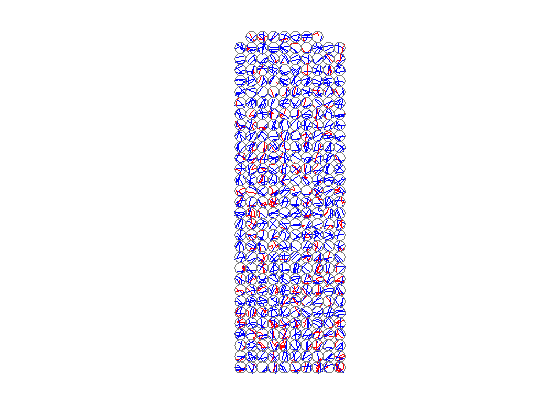

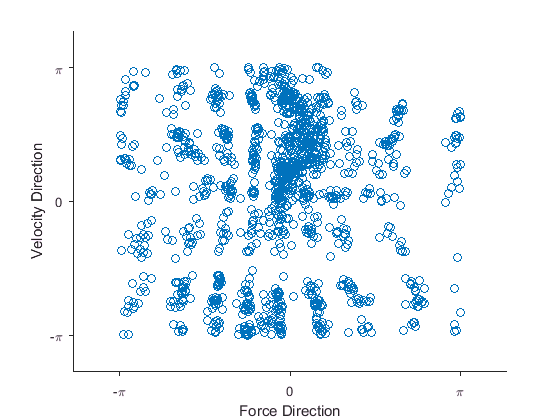

[~,thv,thf] = obs_window_pds(cds);